# Analysis of flight altitude, duration and time of night of geolocator

Labeling of flight was performed manually based on activity data and pressure.

Loading data

addpath(genpath('../functions')) 
addpath("../../BMM-US/functions/light/")
load("../data/processedDataStudyPressure.mat")
scriptAltPres()
load('../data/graph'+project+'.mat')

## Histogram of flight duration

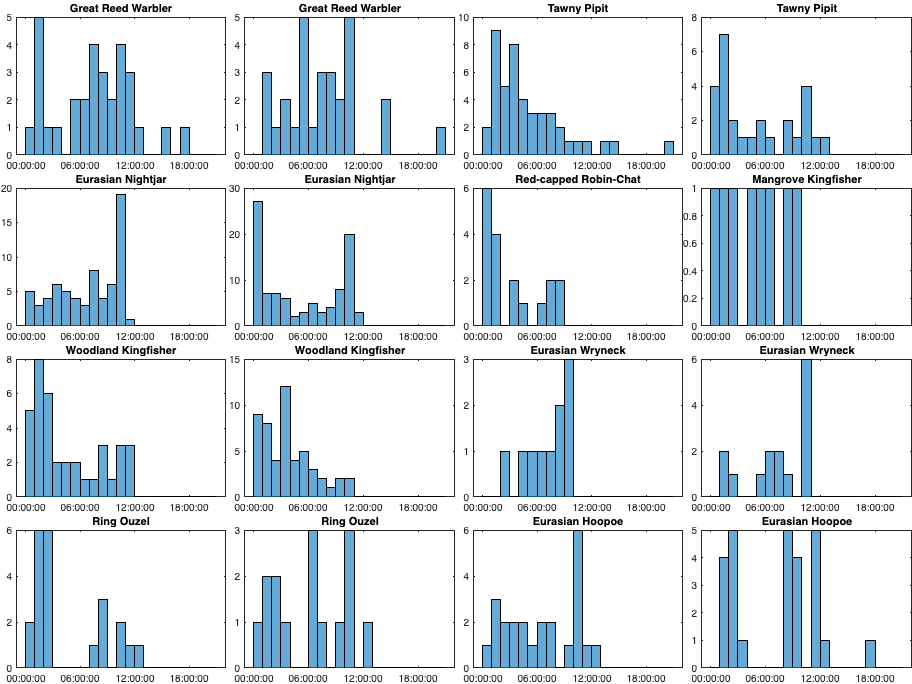

figure('position',[0 0 1000 750]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
tmp=[];
for lt=1:height(tblLog)
    nexttile; box on; hold on; title(tblLog.CommonName{lt})
    histogram(sta{lt}.actDuration(1:end-1),duration(0:1:21,0,0))
    tmp=[tmp;sta{lt}.actDuration(1:end-1)];
end

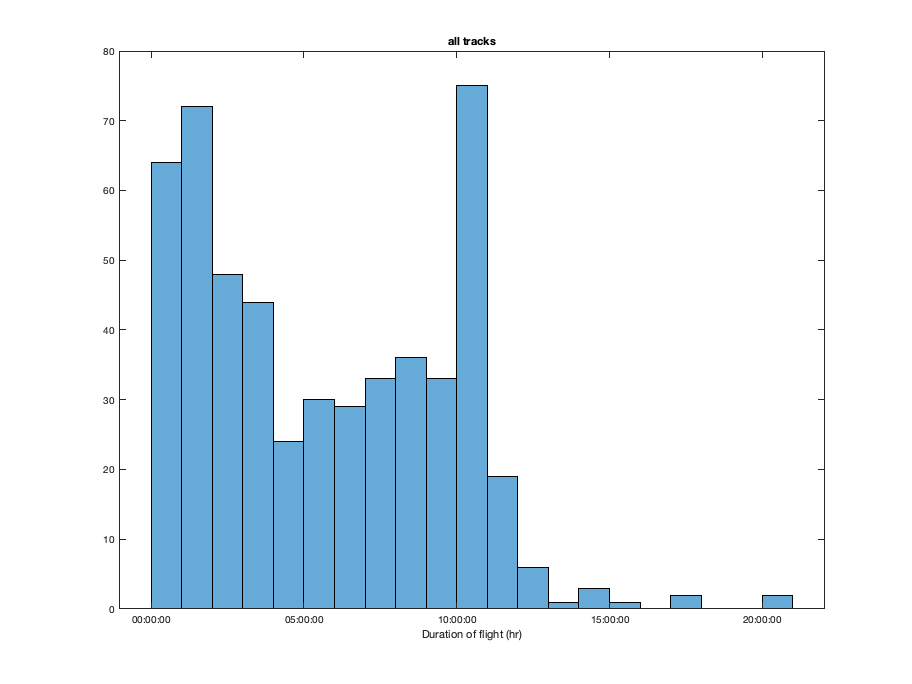

figure('position',[0 0 1000 750]);
histogram(tmp,duration(0:1:21,0,0)); xlabel('Duration of flight (hr)'); title('all tracks')

## Flight altitude over night

Compute the altitude of each flight and convert the time into a normalized time of night: -1 sunset, +1 sunrise. So that 2 would basically be mid-day of the following day. 

Position to compute sunrise and sunset is taken from the result of the model of trajectory. 

Altitude is corrected for temporal change of pressure and provided as meter above sea level.

It could be possible to compute above groundlevel but I'm expecting the changed (~100-300 meters) to be relatively small compare to the altitude variation (~500meter)

clear t alt_tmp
nnt_x=-1:.01:3; 
for lt=1:height(tblLog)
    t{lt} = raw{lt}.pressure.date;
    alt_tmp{lt} = nan(size(t{lt}));
    NNT_tmp{lt} = nan(numel(nnt_x),numel(alt{lt}));
    for i_s=1:numel(alt{lt})
        id = ismember(t{lt},alt{lt}{i_s}.time);
        alt_tmp{lt}(id) = nanmean([alt_tmp{lt}(id) alt{lt}{i_s}.alt],2);
    end
    for i_s=1:numel(alt{lt})-1
        id = sta{lt}.start(i_s+1) >= (t{lt}-median(diff(t{lt}))) &  sta{lt}.end(i_s) <= (t{lt}+median(diff(t{lt})));
        
        [~,i_s_min] = min(abs(sta_sm{lt}.staID - i_s));
        NNT = twilightNNT(t{lt}(id), gr{lt}.sp.lon(i_s_min), gr{lt}.sp.lat(i_s_min),false);
        NNT(logical(cumsum([0;diff(NNT)<0])))=nan;
        if sum(~isnan(NNT))==1
            NNT(find(~isnan(NNT))+1) = NNT((~isnan(NNT)))+0.03;
        end
        NNT = fillmissing(NNT,"linear");
        NNT_tmp{lt}(:,i_s) = interp1(NNT,alt_tmp{lt}(id),nnt_x,"linear");
    end
end

### Figure

rectangle indicates night. 

thick line is average,

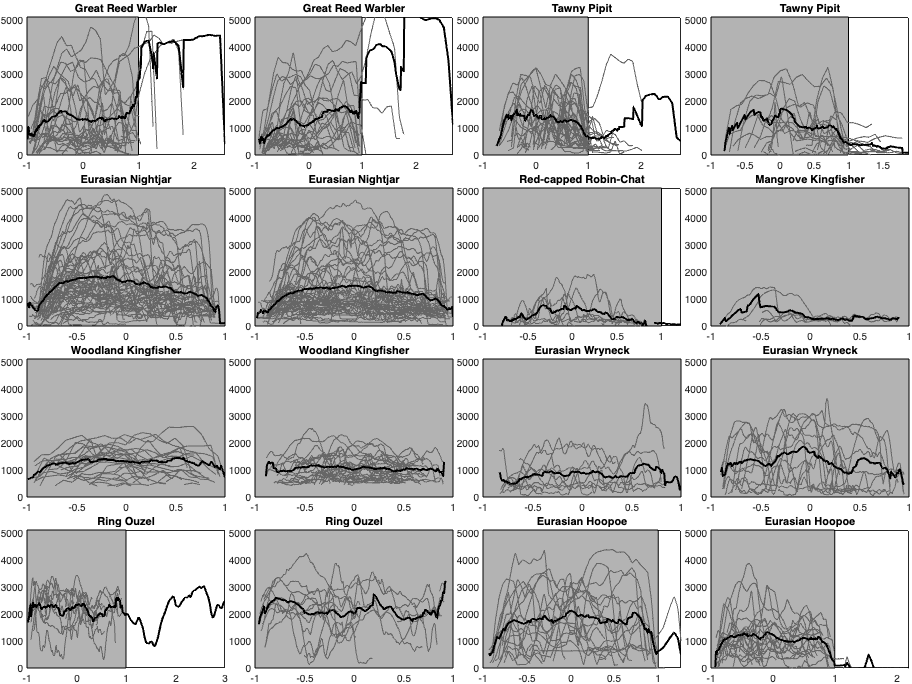

figure('position',[0 0 1000 750]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    nexttile; box on; hold on; title(tblLog.CommonName{lt})
    rectangle('Position',[-1 0 2 5100],'FaceColor',[.7 .7 .7])
    for i_s=1:height(sta{lt})-1
        plot(nnt_x,NNT_tmp{lt}(:,i_s),"color",[.4 .4 .4]); axis tight;
    end
    plot(nnt_x,nanmean(NNT_tmp{lt},2),"k","linewidth",2)
    % plot(nnt_x,quantile(NNT_tmp{lt}',.1),"--k","linewidth",2)
    % plot(nnt_x,quantile(NNT_tmp{lt}',.9),"--k","linewidth",2)
    ylim([0 5100]);
end

### PDF of time of night in flight

rectangle indicates night. 

thick line is average,

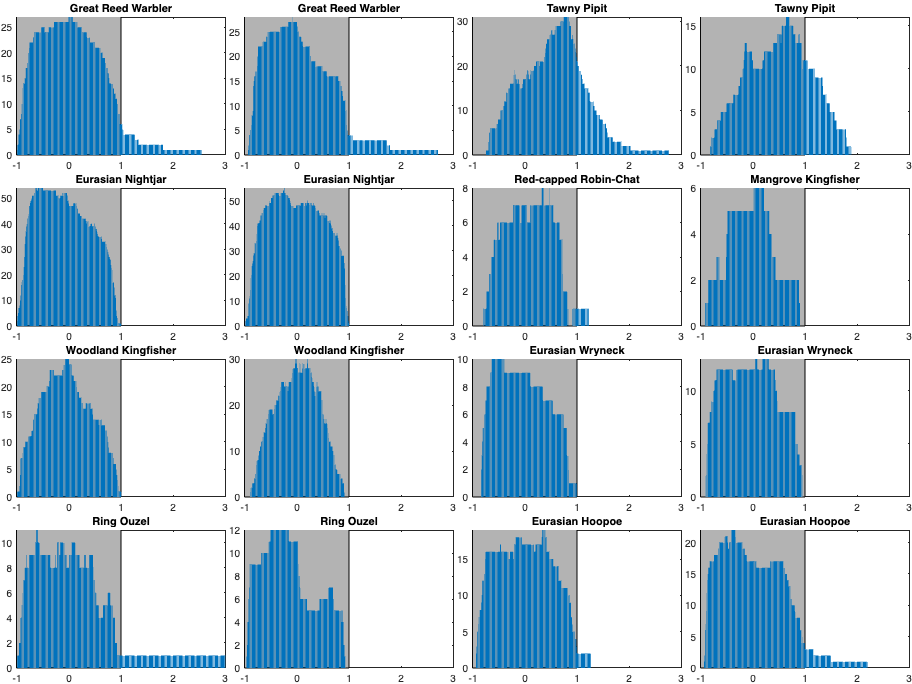

figure('position',[0 0 1000 750]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    nexttile; box on; hold on; title(tblLog.CommonName{lt});
    rectangle('Position',[-1 0 2 5100],'FaceColor',[.7 .7 .7])
    tmp =sum(~isnan(NNT_tmp{lt}),2);
    bar(nnt_x, tmp)
    ylim([0 max(tmp)])
end

## Histogram of altitude 

(x-axis time resolution (5-15min))

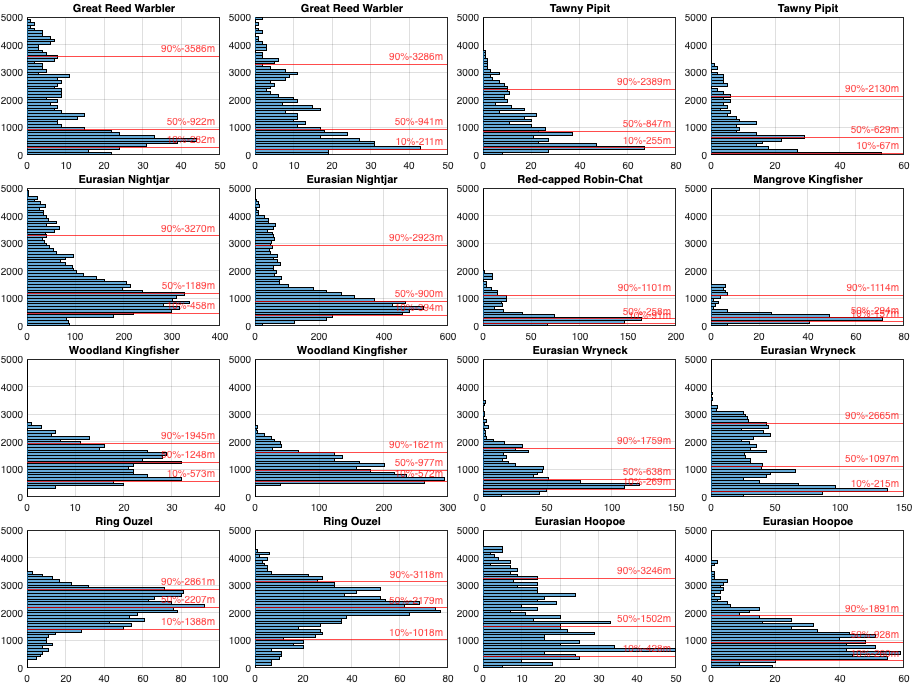

figure('position',[0 0 1000 750]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    nexttile; box on; hold on; title(tblLog.CommonName{lt})
    tmp=[];
    for i_s=1:height(sta{lt})-1
        id = sta{lt}.start(i_s+1) >= (t{lt}-median(diff(t{lt}))) &  sta{lt}.end(i_s) <= (t{lt}+median(diff(t{lt})));
        tmp = [tmp;alt_tmp{lt}(id)];
    end
    histogram(tmp,0:100:5000,'orientation','horizontal');
    tmp2 = quantile(tmp,[.1 .5 .9]);
    yline(tmp2,'-r',["10%-" "50%-" "90%-"]+string(round(tmp2))+"m")
    ylim([0 5000]); grid on;
end

## Flight duration (hours) vs mean altitude

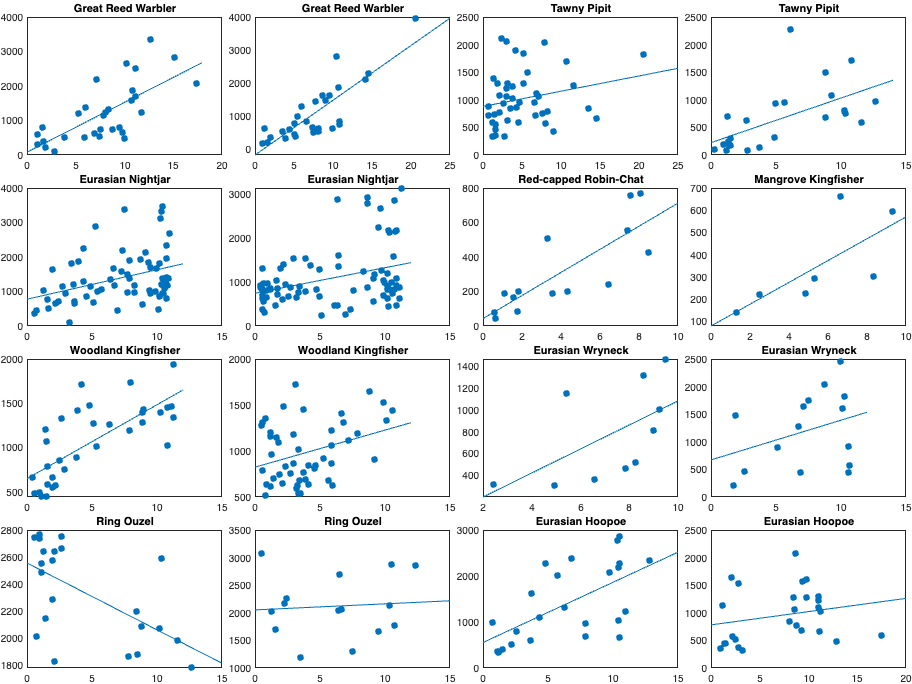

figure('position',[0 0 1000 750]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    nexttile; box on; hold on; title(tblLog.CommonName{lt})
       tmp=[];
    for i_s=1:height(sta{lt})-1
        id = sta{lt}.start(i_s+1) >= (t{lt}-median(diff(t{lt}))) &  sta{lt}.end(i_s) <= (t{lt}+median(diff(t{lt})));
        tmp = [tmp;mean(alt_tmp{lt}(id))];
    end
    id = find(hours(sta_sm{lt}.actDuration)>0);
    plot(hours(sta{lt}.actDuration(id)),tmp(id),'.','MarkerSize',20); lsline;
end

## Flight duration (hours) vs average windspeed

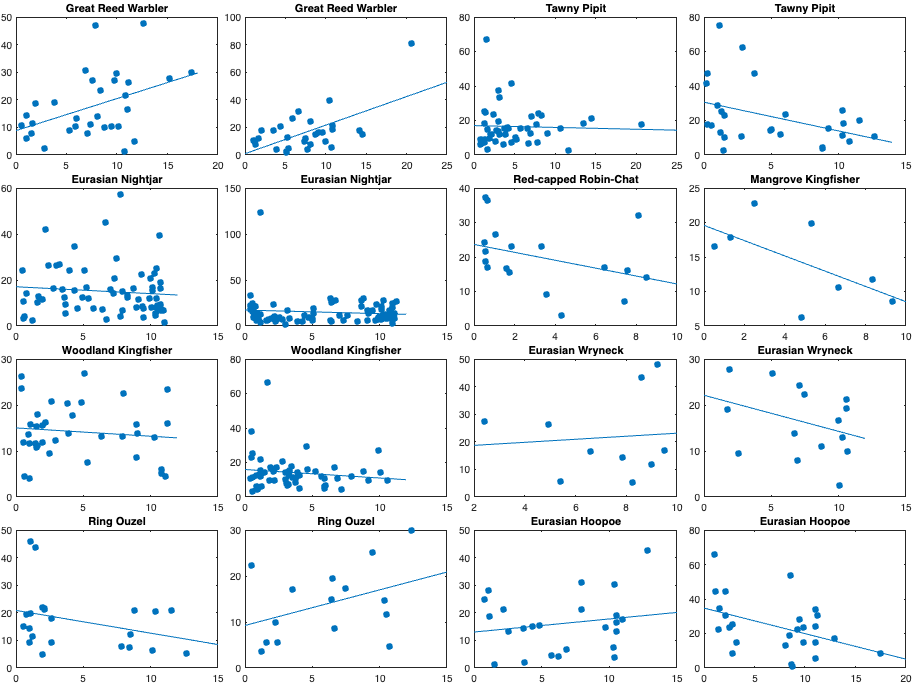

figure('position',[0 0 1000 750]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    nexttile; box on; hold on; title(tblLog.CommonName{lt})
    id = find(hours(sta_sm{lt}.actDuration)>0);
    plot(hours(sta_sm{lt}.actDuration(id)),abs(gr{lt}.sp.ws(id)),'.','MarkerSize',20); lsline;
end

## Flight altitude vs average windspeed (km/h)

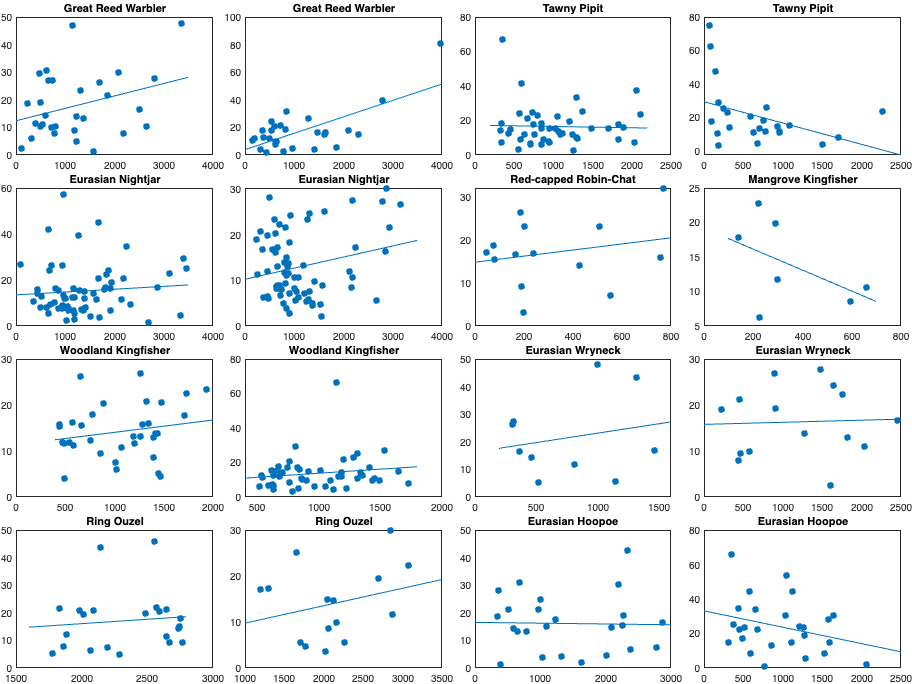

figure('position',[0 0 1000 750]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    nexttile; box on; hold on; title(tblLog.CommonName{lt})
     tmp=[];
    for i_s=1:height(sta_sm{lt})-1
        id = sta_sm{lt}.start(i_s+1) >= (t{lt}-median(diff(t{lt}))) &  sta_sm{lt}.end(i_s) <= (t{lt}+median(diff(t{lt})));
        tmp = [tmp;mean(alt_tmp{lt}(id))];
    end
    id = find(hours(sta_sm{lt}.actDuration)>0);
    plot(tmp(id),abs(gr{lt}.sp.ws(id)),'.','MarkerSize',20); lsline;
end